clc;
clear;
close all;

% Continuous Plant Model
num = [1];
den = [1 3 2];   % Example second order plant
G = tf(num,den);

% Sampling Time
Ts = 0.1;

% Convert to Discrete System
Gz = c2d(G,Ts,'zoh');

disp('Discrete Plant Transfer Function:')

Discrete Plant Transfer Function:


Gz


Gz =
 
  0.004528 z + 0.004097
  ----------------------
  z^2 - 1.724 z + 0.7408
 
Sample time: 0.1 seconds
Discrete-time transfer function.


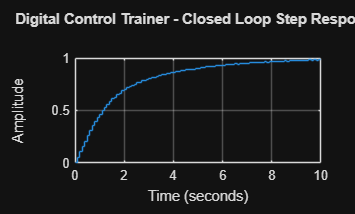


% Digital PID Controller Parameters
Kp = 2;
Ki = 1;
Kd = 0.5;

C = pid(Kp,Ki,Kd);

% Convert controller to discrete form
Cz = c2d(C,Ts,'tustin');

% Closed Loop System
T = feedback(Cz*Gz,1);

% Time vector
t = 0:Ts:10;

% Step Response
figure;
step(T,t);
grid on;
title('Digital Control Trainer - Closed Loop Step Response');

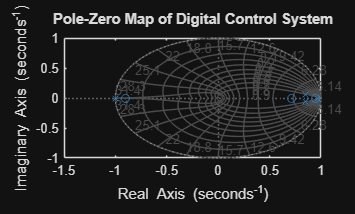


% Plot Poles and Zeros
figure;
pzmap(T);
grid on;
title('Pole-Zero Map of Digital Control System');


% Display System Info
stepinfo(T)

ans = struct with fields:
         RiseTime: 4.7000
    TransientTime: 9.9000
     SettlingTime: 9.9000
      SettlingMin: 0.9016
      SettlingMax: 1.0020
        Overshoot: 0.2003
       Undershoot: 0
             Peak: 1.0020
         PeakTime: 21.9000
